# Actividad 2 (Transformaciones Rotacionales)

Elaborado por:  Marcos Allen Martínez Cortés  |  A01737939

## ROBOT Antropomórfico (6GDL)

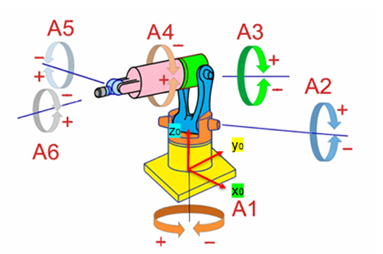

%Limpieza de pantalla
clear all
close all
clc
%SECCIÓN 1
%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t l1 l2 l3 l4 l5
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 2
%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 3
%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5, th6];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(th1(t), th2(t), th3(t), th4(t), th5(t), th6(t))



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 4
%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t), -- th6(t) |
\ dt         dt         dt         dt         dt         dt        /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 5
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 6
%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [0 -sin(th1)  cos(th1);
           0  cos(th1)  sin(th1);
           -1         0       0];


%Junta 2
%Posición de la junta 2 respecto a 1
P(:,:,2)= [-l2*sin(th2); -l2*cos(th2);0];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Junta 3
%Posición de la junta 3 respecto a 2
P(:,:,3)= [-l3*sin(th3); -l3*cos(th3);0];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [cos(th3)  0   sin(th3);
           sin(th3)  0  -cos(th3);
           0         1         0];

%Junta 4
%Posición de la junta 4 respecto a 3
P(:,:,4)= [0; 0; l4];
%Matriz de rotación de la junta 4 respecto a 3
R(:,:,4)= [cos(th4)  0   sin(th4);
           sin(th4)  0  -cos(th4);
           0         1         0];

%Junta 5
%Posición de la junta 5 respecto a 4
P(:,:,5)= [-l5*sin(th5); l5*cos(th5); 0];
%Matriz de rotación de la junta 5 respecto a 4
R(:,:,5)= [cos(th5)  0  -sin(th5);
           sin(th5)  0   cos(th5);
           0         1         0];

%Junta 6
%Posición de la junta 6 respecto a 5
P(:,:,6)= [0; 0;0];
%Matriz de rotación de la junta 6 respecto a 5
R(:,:,6)= [cos(th6) -sin(th6)  0;
           sin(th6)  cos(th6)  0;
           0         0         1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 7
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 8
for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
   %pretty(RO(:,:,i));
   % pretty(RO_inv(:,:,i));
   % pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      l1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación global T1


/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      l1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, -l2 sin(th2(t)) \
|                                               |
| sin(th2(t)),  cos(th2(t)), 0, -l2 cos(th2(t)) |
|                                               |
|      0,            0,      1,        0        |
|                                               |
\      0,            0,      0,        1        /



Matriz de Transformación global T2


/ -sin(th1(t)) sin(th2(t)), -cos(th2(t)) sin(th1(t)), cos(th1(t)),  l2 cos(th2(t)) sin(th1(t)) \
|                                                                                              |
|  cos(th1(t)) sin(th2(t)),  cos(th1(t)) cos(th2(t)), sin(th1(t)), -l2 cos(th1(t)) cos(th2(t)) |
|                                                                                              |
|       -cos(th2(t)),              sin(th2(t)),            0,          l1 + l2 sin(th2(t))     |
|                                                                                              |
\             0,                        0,                 0,                   1              /



Matriz de Transformación local A3


/ cos(th3(t)), 0,  sin(th3(t)), -l3 sin(th3(t)) \
|                                               |
| sin(th3(t)), 0, -cos(th3(t)), -l3 cos(th3(t)) |
|                                               |
|      0,      1,       0,             0        |
|                                               |
\      0,      0,       0,             1        /



Matriz de Transformación global T3


/ -sin(th1(t)) sin(#1), cos(th1(t)),  sin(th1(t)) cos(#1),          sin(th1(t)) #2          \
|                                                                                           |
|  cos(th1(t)) sin(#1), sin(th1(t)), -cos(th1(t)) cos(#1),          -cos(th1(t)) #2         |
|                                                                                           |
|       -cos(#1),            0,            -sin(#1),       l1 + l2 sin(th2(t)) - l3 sin(#3) |
|                                                                                           |
\           0,               0,                0,                          1                /

where

   #1 == th2(t) + th3(t)

   #2 == l2 cos(th2(t)) + l3 cos(#3)

   #3 == th2(t) - th3(t)




Matriz de Transformación local A4


/ cos(th4(t)), 0,  sin(th4(t)),  0 \
|                                  |
| sin(th4(t)), 0, -cos(th4(t)),  0 |
|                                  |
|      0,      1,       0,      l4 |
|                                  |
\      0,      0,       0,       1 /



Matriz de Transformación global T4


/ cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#1),  sin(th1(t)) cos(#1), - cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) sin(#1),    sin(th1(t)) #2 + l4 sin(th1(t)) cos(#1)    \
|                                                                                                                                                                                             |
| sin(th1(t)) sin(th4(t)) + cos(th1(t)) cos(th4(t)) sin(#1), -cos(th1(t)) cos(#1),  cos(th1(t)) sin(th4(t)) sin(#1) - cos(th4(t)) sin(th1(t)),    - cos(th1(t)) #2 - l4 cos(th1(t)) cos(#1)   |
|                                                                                                                                                                                             |
|                    -cos(th4(t)) cos(#1),                         -sin(#1),                           -sin(th4(t)) cos(#1),                    l1 + l2 sin(th2(t)) - l4 sin(#1) - l3 sin(#3) |
|                                       

Matriz de Transformación local A5


/ cos(th5(t)), 0, -sin(th5(t)), -l5 sin(th5(t)) \
|                                               |
| sin(th5(t)), 0,  cos(th5(t)),  l5 cos(th5(t)) |
|                                               |
|      0,      1,       0,             0        |
|                                               |
\      0,      0,       0,             1        /



Matriz de Transformación global T5


/     cos(th5(t)) #1 + sin(th1(t)) sin(th5(t)) cos(#4),    - cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) sin(#4),    cos(th5(t)) sin(th1(t)) cos(#4) - sin(th5(t)) #1,         sin(th1(t)) #3 - l5 sin(th5(t)) #1 + l4 sin(th1(t)) cos(#4) + l5 cos(th5(t)) sin(th1(t)) cos(#4)      \
|                                                                                                                                                                                                                                                                                          |
|     cos(th5(t)) #2 - cos(th1(t)) sin(th5(t)) cos(#4),     cos(th1(t)) sin(th4(t)) sin(#4) - cos(th4(t)) sin(th1(t)),    - sin(th5(t)) #2 - cos(th1(t)) cos(th5(t)) cos(#4),       - cos(th1(t)) #3 - l5 sin(th5(t)) #2 - l4 cos(th1(t)) cos(#4) - l5 cos(th1(t)) cos(th5(t)) cos(#4)     |
|                                                                                                                                                

Matriz de Transformación local A6


/ cos(th6(t)), -sin(th6(t)), 0, 0 \
|                                 |
| sin(th6(t)),  cos(th6(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación global T6


/           cos(th6(t)) #3 - sin(th6(t)) #2,                   - sin(th6(t)) #3 - cos(th6(t)) #2,            cos(th5(t)) sin(th1(t)) cos(#10) - sin(th5(t)) #7,          sin(th1(t)) #6 - l5 sin(th5(t)) #7 + l4 sin(th1(t)) cos(#10) + l5 cos(th5(t)) sin(th1(t)) cos(#10)       \
|                                                                                                                                                                                                                                                                                 |
|           cos(th6(t)) #5 - sin(th6(t)) #1,                   - sin(th6(t)) #5 - cos(th6(t)) #1,           - sin(th5(t)) #8 - cos(th1(t)) cos(th5(t)) cos(#10),        - cos(th1(t)) #6 - l5 sin(th5(t)) #8 - l4 cos(th1(t)) cos(#10) - l5 cos(th1(t)) cos(th5(t)) cos(#10)      |
|                                                                                                                                                                           

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));

%SECCIÓN 9
%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 [...] y th6
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);
Jv16= functionalDerivative(PO(1,1,GDL), th6);
%Derivadas parciales de y respecto a th1 [...] y th6
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);
Jv26= functionalDerivative(PO(2,1,GDL), th6);
%Derivadas parciales de z respecto a th1 [...] y th6
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);
Jv36= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36]);
pretty(jv_d);

/ l3 cos(th1(t)) cos(#7) + l2 cos(th1(t)) cos(th2(t)) + l4 cos(th1(t)) cos(#8) + l5 sin(th1(t)) sin(th4(t)) sin(th5(t)) + l5 cos(th1(t)) cos(th5(t)) cos(#8) + l5 cos(th1(t)) cos(th4(t)) sin(th5(t)) sin(#8),                   -sin(th1(t)) #1,                           -sin(th1(t)) #2,          -l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) + sin(th1(t)) sin(th4(t)) sin(#8)), l5 cos(th4(t)) cos(th5(t)) sin(th1(t)) sin(#8) - l5 cos(th1(t)) cos(th5(t)) sin(th4(t)) - l5 sin(th1(t)) sin(th5(t)) cos(#8), 0 \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 10
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
        end
        
        %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ cos(th1(t)) #11 + l5 sin(th5(t)) (sin(th1(t)) sin(th4(t)) + cos(th1(t)) cos(th4(t)) sin(#16)) + l4 cos(th1(t)) cos(#16) + l5 cos(th1(t)) cos(th5(t)) cos(#16),               -sin(th1(t)) #9,                          -sin(th1(t)) #10,           -l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) + sin(th1(t)) sin(th4(t)) sin(#16)), l5 cos(th4(t)) cos(th5(t)) sin(th1(t)) sin(#16) - l5 cos(th1(t)) cos(th5(t)) sin(th4(t)) - l5 sin(th1(t)) sin(th5(t)) cos(#16), 0 \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                    |
| sin(th1(t)) #11 - l5 sin(th5(t)) (cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, cos(th1(t)), cos(th1(t)),  sin(th1(t)) cos(#1), - cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) sin(#1),  cos(th5(t)) sin(th1(t)) cos(#1) - sin(th5(t)) (cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#1))  \
|                                                                                                                                                                                                                             |
| 0, sin(th1(t)), sin(th1(t)), -cos(th1(t)) cos(#1),  cos(th1(t)) sin(th4(t)) sin(#1) - cos(th4(t)) sin(th1(t)),  - sin(th5(t)) (sin(th1(t)) sin(th4(t)) + cos(th1(t)) cos(th4(t)) sin(#1)) - cos(th1(t)) cos(th5(t)) cos(#1) |
|                                                                                                                                                                                                                             |
\ 1,      0,           0,            -sin(#1),                           -sin(th4(t)) cos(#1),          



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ #13 (cos(th1(t)) #16 + l5 sin(th5(t)) (sin(th1(t)) sin(th4(t)) + cos(th1(t)) cos(th4(t)) sin(#21)) + l4 cos(th1(t)) cos(#21) + l5 cos(th1(t)) cos(th5(t)) cos(#21)) - #5 (l5 sin(th1(t)) sin(th5(t)) cos(#21) + l5 cos(th1(t)) cos(th5(t)) sin(th4(t)) - l5 cos(th4(t)) cos(th5(t)) sin(th1(t)) sin(#21)) - #7 sin(th1(t)) #15 - #8 sin(th1(t)) #14 - l5 #6 sin(th5(t)) (cos(th1(t)) cos(th4(t)) + sin(th1(t)) sin(th4(t)) sin(#21)) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                      |
| #13 (sin(th1(t)) #16 - l5 sin(th5(t)) (cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#21)) + l4 sin(th1(t)) cos(#21) + l5 cos(th5(t)) sin(th

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ #6 cos(th1(t)) - #2 (cos(th1(t)) cos(th4(t)) + sin(th1(t)) sin(th4(t)) sin(#4)) - #1 (sin(th5(t)) (cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#4)) - cos(th5(t)) sin(th1(t)) cos(#4)) + #5 cos(th1(t)) + #3 sin(th1(t)) cos(#4) \
|                                                                                                                                                                                                                                            |
| #6 sin(th1(t)) - #2 (cos(th4(t)) sin(th1(t)) - cos(th1(t)) sin(th4(t)) sin(#4)) - #1 (sin(th5(t)) (sin(th1(t)) sin(th4(t)) + cos(th1(t)) cos(th4(t)) sin(#4)) + cos(th1(t)) cos(th5(t)) cos(#4)) + #5 sin(th1(t)) - #3 cos(th1(t)) cos(#4) |
|                                                                                                                                                                                                                                            |
|                                           


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## ROBOT Industrial (6GDL)

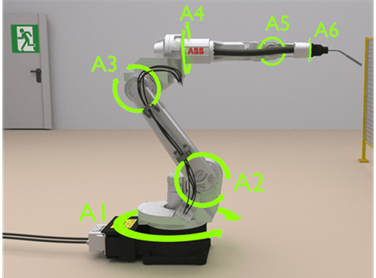

%Limpieza de pantalla
clear all
close all
clc
%SECCIÓN 1
%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t h l1 l2 l3 l4 l5
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 2
%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 3
%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5, th6];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(th1(t), th2(t), th3(t), th4(t), th5(t), th6(t))



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 4
%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t), -- th6(t) |
\ dt         dt         dt         dt         dt         dt        /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 5
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 6
%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [sqrt(l1^2-h^2)*sin(th1); -(sqrt(l1^2-h^2)*cos(th1)); h];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1)  0   sin(th1);
           sin(th1)  0  -cos(th1);
           0         1         0];


%Junta 2
%Posición de la junta 2 respecto a 1
P(:,:,2)= [-l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Junta 3
%Posición de la junta 3 respecto a 2
P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [0 -sin(th3)  cos(th3);
           0  cos(th3)  sin(th3);
           -1       0         0];

%Junta 4
%Posición de la junta 4 respecto a 3
P(:,:,4)= [0; 0; l4];
%Matriz de rotación de la junta 4 respecto a 3
R(:,:,4)= [0  -sin(th4)  -cos(th4);
           0   cos(th4)  -sin(th4);
           1         0          0];

%Junta 5
%Posición de la junta 5 respecto a 4
P(:,:,5)= [l5*cos(th5); l5*sin(th5);0];
%Matriz de rotación de la junta 5 respecto a 4
R(:,:,5)= [0 -sin(th5)  cos(th5);
           0  cos(th5)  sin(th5);
           -1       0         0];

%Junta 6
%Posición de la junta 6 respecto a 5
P(:,:,6)= [0; 0;0];
%Matriz de rotación de la junta 6 respecto a 5
R(:,:,6)= [cos(th6) -sin(th6)  0;
           sin(th6)  cos(th6)  0;
           0         0         1];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 7
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 8
for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
   %pretty(RO(:,:,i));
   % pretty(RO_inv(:,:,i));
   % pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/                                                   2    2  \
| cos(th1(t)), 0,  sin(th1(t)),  sin(th1(t)) sqrt(l1  - h ) |
|                                                           |
|                                                   2    2  |
| sin(th1(t)), 0, -cos(th1(t)), -cos(th1(t)) sqrt(l1  - h ) |
|                                                           |
|      0,      1,       0,                   h              |
|                                                           |
\      0,      0,       0,                   1              /



Matriz de Transformación global T1


/                                                   2    2  \
| cos(th1(t)), 0,  sin(th1(t)),  sin(th1(t)) sqrt(l1  - h ) |
|                                                           |
|                                                   2    2  |
| sin(th1(t)), 0, -cos(th1(t)), -cos(th1(t)) sqrt(l1  - h ) |
|                                                           |
|      0,      1,       0,                   h              |
|                                                           |
\      0,      0,       0,                   1              /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, -l2 cos(th2(t)) \
|                                               |
| sin(th2(t)),  cos(th2(t)), 0,  l2 sin(th2(t)) |
|                                               |
|      0,            0,      1,        0        |
|                                               |
\      0,            0,      0,        1        /



Matriz de Transformación global T2


/ cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)),  sin(th1(t)),  sin(th1(t)) #1 - l2 cos(th1(t)) cos(th2(t))  \
|                                                                                                                |
| cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)), -cos(th1(t)), - cos(th1(t)) #1 - l2 cos(th2(t)) sin(th1(t)) |
|                                                                                                                |
|       sin(th2(t)),              cos(th2(t)),             0,                    h + l2 sin(th2(t))              |
|                                                                                                                |
\            0,                        0,                  0,                            1                       /

where

                2    2
   #1 == sqrt(l1  - h )




Matriz de Transformación local A3


/  0, -sin(th3(t)), cos(th3(t)), l3 cos(th3(t)) \
|                                               |
|  0,  cos(th3(t)), sin(th3(t)), l3 sin(th3(t)) |
|                                               |
| -1,       0,           0,             0       |
|                                               |
\  0,       0,           0,             1       /



Matriz de Transformación global T3


/ -sin(th1(t)), -cos(th1(t)) sin(#2), cos(th1(t)) cos(#2), sin(th1(t)) #1 - l2 cos(th1(t)) cos(th2(t)) + l3 cos(th1(t)) cos(th2(t)) cos(th3(t)) - l3 cos(th1(t)) sin(th2(t)) sin(th3(t)) \
|                                                                                                                                                                                        |
|  cos(th1(t)), -sin(th1(t)) sin(#2), sin(th1(t)) cos(#2), l3 cos(th2(t)) cos(th3(t)) sin(th1(t)) - l2 cos(th2(t)) sin(th1(t)) - cos(th1(t)) #1 - l3 sin(th1(t)) sin(th2(t)) sin(th3(t)) |
|                                                                                                                                                                                        |
|       0,             cos(#2),             sin(#2),                                                      h + l2 sin(th2(t)) + l3 sin(#2)                                                |
|                                                                

Matriz de Transformación local A4


/ 0, -sin(th4(t)), -cos(th4(t)),  0 \
|                                   |
| 0,  cos(th4(t)), -sin(th4(t)),  0 |
|                                   |
| 1,       0,            0,      l4 |
|                                   |
\ 0,       0,            0,       1 /



Matriz de Transformación global T4


/ cos(th1(t)) cos(#2),  sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) sin(#2),  cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) sin(#2), sin(th1(t)) #1 - l2 cos(th1(t)) cos(th2(t)) + l4 cos(th1(t)) cos(#2) + l3 cos(th1(t)) cos(th2(t)) cos(th3(t)) - l3 cos(th1(t)) sin(th2(t)) sin(th3(t)) \
|                                                                                                                                                                                                                                                                                                     |
| sin(th1(t)) cos(#2), - cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#2), sin(th1(t)) sin(th4(t)) sin(#2) - cos(th1(t)) cos(th4(t)), l4 sin(th1(t)) cos(#2) - l2 cos(th2(t)) sin(th1(t)) - cos(th1(t)) #1 + l3 cos(th2(t)) cos(th3(t)) sin(th1(t)) - l3 sin(th1(t)) sin(th2(t)) sin(th3(t)) |
|                                                                                                               

Matriz de Transformación local A5


/  0, -sin(th5(t)), cos(th5(t)), l5 cos(th5(t)) \
|                                               |
|  0,  cos(th5(t)), sin(th5(t)), l5 sin(th5(t)) |
|                                               |
| -1,       0,           0,             0       |
|                                               |
\  0,       0,           0,             1       /



Matriz de Transformación global T5


/ - cos(th4(t)) sin(th1(t)) - cos(th1(t)) sin(th4(t)) sin(#4),    cos(th5(t)) #2 - cos(th1(t)) sin(th5(t)) cos(#4),      sin(th5(t)) #2 + cos(th1(t)) cos(th5(t)) cos(#4),   sin(th1(t)) #1 + l5 sin(th5(t)) #2 - l2 cos(th1(t)) cos(th2(t)) + l4 cos(th1(t)) cos(#4) + l3 cos(th1(t)) cos(th2(t)) cos(th3(t)) - l3 cos(th1(t)) sin(th2(t)) sin(th3(t)) + l5 cos(th1(t)) cos(th5(t)) cos(#4) \
|                                                                                                                                                                                                                                                                                                                                                                                            |
|  cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) sin(#4),    - cos(th5(t)) #3 - sin(th1(t)) sin(th5(t)) cos(#4),     cos(th5(t)) sin(th1(t)) cos(#4) - sin(th5(t)) #3,   l4 sin(th1(t)) cos(#4) - l5 sin(th5(t)) #3 - l2 cos(th2(t)) s

Matriz de Transformación local A6


/ cos(th6(t)), -sin(th6(t)), 0, 0 \
|                                 |
| sin(th6(t)),  cos(th6(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación global T6


/          sin(th6(t)) #6 - cos(th6(t)) #3,                   cos(th6(t)) #6 + sin(th6(t)) #3,             sin(th5(t)) #8 + cos(th1(t)) cos(th5(t)) cos(#9),   sin(th1(t)) #1 + l5 sin(th5(t)) #8 - l2 cos(th1(t)) cos(th2(t)) + l4 cos(th1(t)) cos(#9) + l3 cos(th1(t)) cos(th2(t)) cos(th3(t)) - l3 cos(th1(t)) sin(th2(t)) sin(th3(t)) + l5 cos(th1(t)) cos(th5(t)) cos(#9) \
|                                                                                                                                                                                                                                                                                                                                                                              |
|          cos(th6(t)) #2 - sin(th6(t)) #4,                  - cos(th6(t)) #4 - sin(th6(t)) #2,            cos(th5(t)) sin(th1(t)) cos(#9) - sin(th5(t)) #7,   l4 sin(th1(t)) cos(#9) - l5 sin(th5(t)) #7 - l2 cos(th2(t)) sin(th1(t)) - cos(th1(t)) #1 + l5 cos(th5(t

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));

%SECCIÓN 9
%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 [...] y th6
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);
Jv16= functionalDerivative(PO(1,1,GDL), th6);
%Derivadas parciales de y respecto a th1 [...] y th6
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);
Jv26= functionalDerivative(PO(2,1,GDL), th6);
%Derivadas parciales de z respecto a th1 [...] y th6
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);
Jv36= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36]);
pretty(jv_d);

/ cos(th1(t)) #1 + l2 cos(th2(t)) sin(th1(t)) - l4 sin(th1(t)) cos(#10) - l5 cos(th5(t)) sin(th1(t)) cos(#10) - l3 cos(th2(t)) cos(th3(t)) sin(th1(t)) + l5 cos(th1(t)) sin(th4(t)) sin(th5(t)) + l3 sin(th1(t)) sin(th2(t)) sin(th3(t)) + l5 cos(th4(t)) sin(th1(t)) sin(th5(t)) sin(#10),                    -cos(th1(t)) #2,                             -cos(th1(t)) #3,            l5 sin(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) sin(#10)),  l5 cos(th5(t)) sin(th1(t)) sin(th4(t)) - l5 cos(th1(t)) sin(th5(t)) cos(#10) - l5 cos(th1(t)) cos(th4(t)) cos(th5(t)) sin(#10),  0 \
|                                                                                                                                                                                                                                                                                                                                                                                                                            

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 10
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
        end
        
        %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ cos(th1(t)) #9 + l5 sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) sin(#14)) + l2 cos(th2(t)) sin(th1(t)) - l4 sin(th1(t)) cos(#14) - l5 cos(th5(t)) sin(th1(t)) cos(#14) - l3 cos(th2(t)) cos(th3(t)) sin(th1(t)) + l3 sin(th1(t)) sin(th2(t)) sin(th3(t)),                    -cos(th1(t)) #10,                               -cos(th1(t)) #11,            l5 sin(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) sin(#14)),  l5 cos(th5(t)) sin(th1(t)) sin(th4(t)) - l5 cos(th1(t)) sin(th5(t)) cos(#14) - l5 cos(th1(t)) cos(th4(t)) cos(th5(t)) sin(#14),  0 \
|                                                                                                                                                                                                                                                                                                                                                                                                                                     

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, sin(th1(t)), sin(th1(t)), cos(th1(t)) cos(#1), cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) sin(#1), sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) sin(#1)) + cos(th1(t)) cos(th5(t)) cos(#1) \
|                                                                                                                                                                                                                        |
| 0,      #2,          #2,     sin(th1(t)) cos(#1), sin(th1(t)) sin(th4(t)) sin(#1) - cos(th1(t)) cos(th4(t)), cos(th5(t)) sin(th1(t)) cos(#1) - sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) sin(#1)) |
|                                                                                                                                                                                                                        |
\ 1,      0,           0,            sin(#1),                          -sin(th4(t)) cos(#1),                                



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ #14 (cos(th1(t)) #13 + l5 sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) sin(#19)) + l2 cos(th2(t)) sin(th1(t)) - l4 sin(th1(t)) cos(#19) - l5 cos(th5(t)) sin(th1(t)) cos(#19) - l3 cos(th2(t)) cos(th3(t)) sin(th1(t)) + l3 sin(th1(t)) sin(th2(t)) sin(th3(t))) - #5 (l5 cos(th1(t)) sin(th5(t)) cos(#19) - l5 cos(th5(t)) sin(th1(t)) sin(th4(t)) + l5 cos(th1(t)) cos(th4(t)) cos(th5(t)) sin(#19)) - #7 cos(th1(t)) #16 - #8 cos(th1(t)) #15 + l5 #6 sin(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) sin(#19)) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ #1 (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) sin(#4)) + cos(th1(t)) cos(th5(t)) cos(#4)) + #2 (cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) sin(#4)) + #6 sin(th1(t)) + #5 sin(th1(t)) + #3 cos(th1(t)) cos(#4) \
|                                                                                                                                                                                                                                            |
| #3 sin(th1(t)) cos(#4) - #2 (cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) sin(#4)) - #6 cos(th1(t)) - #5 cos(th1(t)) - #1 (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) sin(#4)) - cos(th5(t)) sin(th1(t)) cos(#4)) |
|                                                                                                                                                                                                                                            |
|                                           


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%